## Kalman Filter Example

The car example with two states x=(p, v)'.

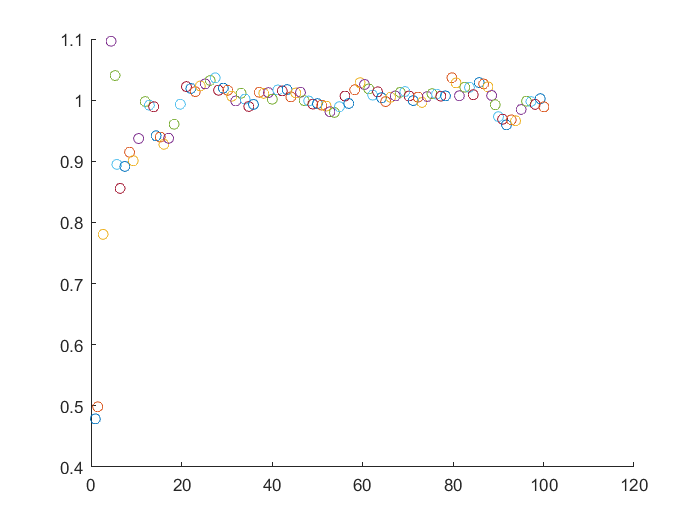

Z = (1:100);    % 观测值
noise = randn(1, 100);  % 方差为1的高斯噪声
Z = Z + noise;

dt = 1;

U = [0];    % 输入变量
B = [dt*dt/2; dt];  % 控制矩阵
X = [0; 0]; % 状态
P = [1 0; 0 1]; % 状态协方差矩阵
F = [1 1; 0 1]; % 状态转移矩阵
Q = [0.0001, 0; 0 0.0001];  % 状态转移协方差矩阵 - 状态转移产生的噪声, 认为预测模型非常准确，因此设置协方差很小
H = [1 0];  % 观测矩阵
R = 1;  % 观测噪声方差

figure
hold on

for i=1:100
    X_ = F*X + B*U; % 状态预测
    P_ = F*P*F' + Q;    % 噪声预测
    K = P_*H'*(H*P_*H'+R)^-1;   % 卡尔曼增益
    X = X_ + K*(Z(i) - H*X_);  % 状态更新
    P = (eye(2) - K*H)*P_;  % 不确定性更新
    
    plot(X(1), X(2), 'o');
    pause(0.01)
end